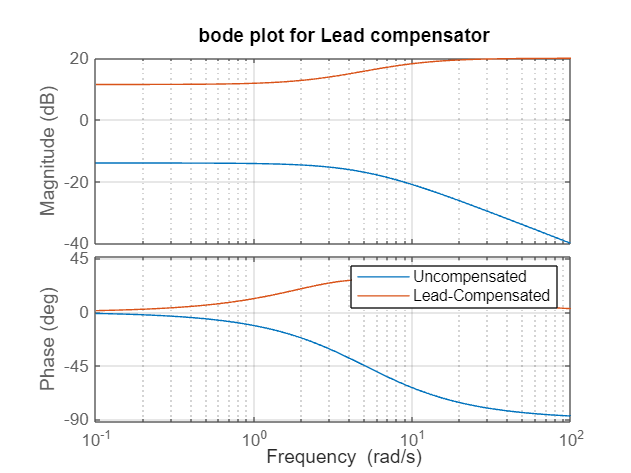

%NAME: WYCLIFFE MACHUKI OKENYE
%REG: EG209/106813/21
%CONTROL ASSIGNMENT
s = tf('s');
G1 = 1/(s + 5);
C_lead = 9*(s +3)/(s + 9);
C_lag = (s + 2)/(s + 0.2);
C_total= G1*C_lead*C_lag;
C_L=feedback(C_total,1);
%%c_lead bode plots
figure;
bode(G1, C_lead);
grid on;
title('bode plot for Lead compensator')
legend('Uncompensated', 'Lead-Compensated')

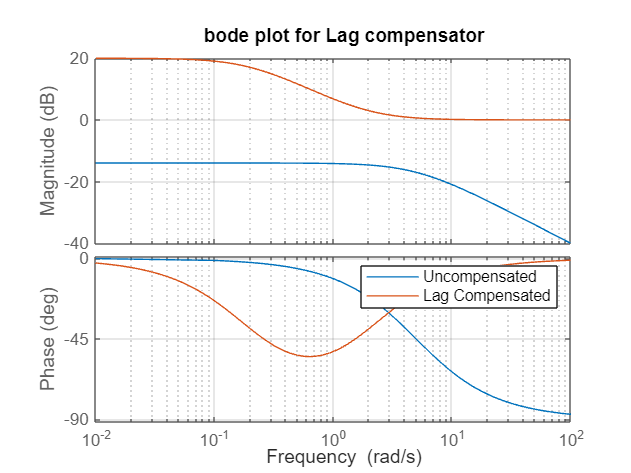


%%C-lag bode plot
figure;
bode(G1, C_lag);
grid on;
title('bode plot for Lag compensator')
legend('Uncompensated', 'Lag Compensated')

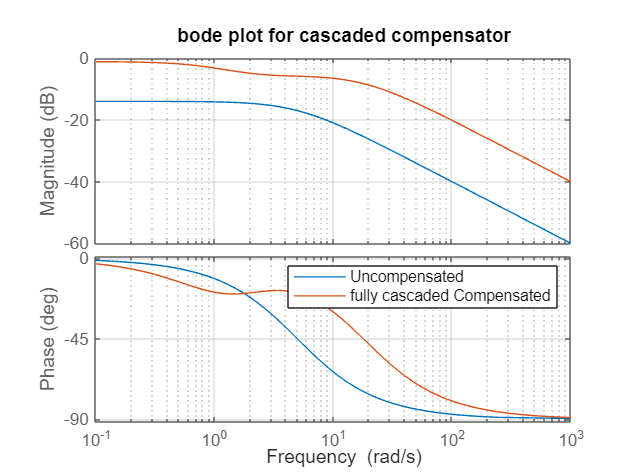

%%bode plot for compensated ssytem
figure;
bode(G1,C_L);
grid on;
title('bode plot for cascaded compensator')
legend('Uncompensated', 'fully Compensated')

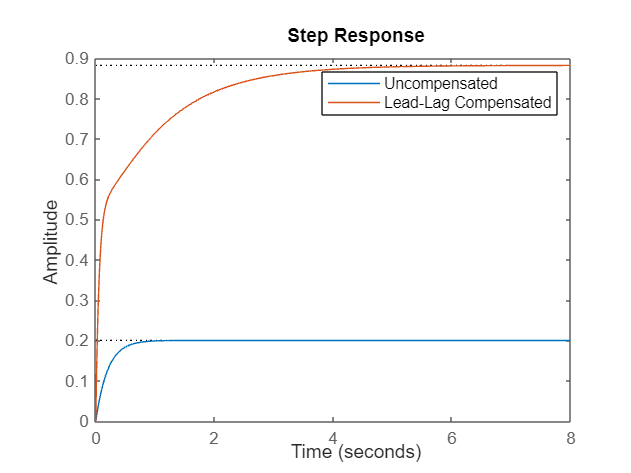


%%plotting the step response
step(G1, C_L)
legend('Uncompensated', 'Lead-Lag Compensated')